# **データとは何か**

2024年7月16日(火) 1限

千原浩之

8:30-9:40    Zoom による講義

- 高等学校 情報I-II

- 数ベクトルや行列を扱う線形代数という数学

- 数ベクトルや行列が表すさまざまなデータ

- データ処理と線形代数

9:40-10:00    WebClass の試験機能による課題

- 複数選択式演習問題(回答回数制限2回)

この資料

- **MATLAB** という商業プログラミング言語の live script というノートブックのファイル *.mlx である。

- **LaTeX** による数式を含めた記述・プログラムコード・出力を一体化している。

## 1. 高等学校 情報I-II

担当教員はハイレベルだと評判の高い[**実教出版の教科書**](https://www.jikkyo.co.jp/highschool/jouhou/)をざっと眺めただけだが...

**情報I**

- 2022年度に導入された高校1年生向け必修科目である。

- 話題は情報リテラシーと初等的な計算機スキルである。

- **computational thinking** の最初の一歩という点が強調されている。 

- 発展的話題に公開データの活用、および、データの可視化がある。

- といってもシンガポールの小学校の必修科目 spreadsheet レベルの話題である。 

**情報II**

- 2023年度に導入された高校2年生向け選択科目である。

- 話題はプログラミング言語による初等的データ処理と「おはなし」である。

- 生成型AIの基礎となるtransformer などの「おはなし」がないので既に時代遅れな感じがする。

- 理工系大学1-2年程度の数学を基盤とする話題を無理やり説明を試みる。

- RSA暗号：初等整数論におけるフェルマーの小定理が必要だが...

- 深層学習：多変数関数の微分積分における極値の基礎理論や計算法が必要だが...

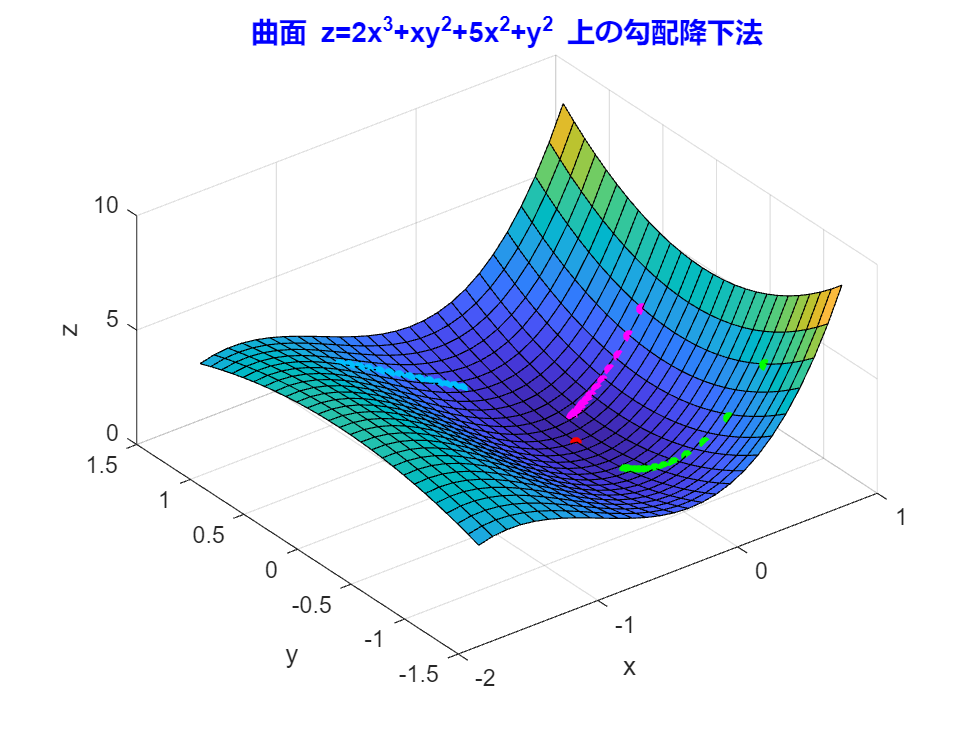

close;

[x,y]=meshgrid(-1.7:0.1:0.9,-1.3:0.1:1.3);
z=2*x.^3+x.*y.^2+5*x.^2+y.^2;

P=zeros(3,1);

X=zeros(3,100);
X(1,1)=0.7;
X(2,1)=0.3;
s=0.01;
for j=1:99
    X(1,j+1)=X(1,j)-s*(6*X(1,j)^2+X(2,j)^2+10*X(1,j));
    X(2,j+1)=X(2,j)-s*(2*X(1,j)*X(2,j)+2*X(2,j));
end
X(3,:)=2*X(1,:).^3+X(1,:).*X(2,:).^2+5*X(1,:).^2+X(2,:).^2;

Y=zeros(3,100);
Y(1,1)=0.7;
Y(2,1)=-0.85;
s=0.02;
for j=1:99
    Y(1,j+1)=Y(1,j)-s*(6*Y(1,j)^2+Y(2,j)^2+10*Y(1,j));
    Y(2,j+1)=Y(2,j)-s*(2*Y(1,j)*Y(2,j)+2*Y(2,j));
end
Y(3,:)=2*Y(1,:).^3+Y(1,:).*Y(2,:).^2+5*Y(1,:).^2+Y(2,:).^2;

Z=zeros(3,100);
Z(1,1)=-1;
Z(2,1)=0.9;
s=0.02;
for j=1:99
    Z(1,j+1)=Z(1,j)-s*(6*Z(1,j)^2+Z(2,j)^2+10*Z(1,j));
    Z(2,j+1)=Z(2,j)-s*(2*Z(1,j)*Z(2,j)+2*Z(2,j));
end
Z(3,:)=2*Z(1,:).^3+Z(1,:).*Z(2,:).^2+5*Z(1,:).^2+Z(2,:).^2;

N =14;

r=surf(x,y,z);
pbaspect([2 2 1])
title('曲面 z=2x^3+xy^2+5x^2+y^2 上の勾配降下法','Color','blue','FontSize',12)
xlabel('x')
ylabel('y')
zlabel('z')
hold on
newcolors = [1 0 0; 
             1 0 1;
             0 1 0; 
             0 191/255 1];
colororder(newcolors)        
plot3(P(1,:),P(2,:),P(3,:),'.', ...
    X(1,1:N),X(2,1:N),X(3,1:N),'.', ...
    Y(1,1:N),Y(2,1:N),Y(3,1:N),'.', ...
    Z(1,1:N),Z(2,1:N),Z(3,1:N),'.','MarkerSize',15)
hold off

### **1-1. 従来の深層学習とAIの設計の最先端理論の1つである幾何学的深層学習**

- 従来のAI (artificial intelligence) の枠組みは下位から上位の順に 深層学習 $\subset$ 機械学習 $\subset$ AI であった。

- 従来の深層学習の神経回路網の各層は単なる集合であるが、それをグラフ(有限個の頂点と辺から構成された図形)のようなある種の幾何学的構造をもつ空間に置き換えたものが幾何学的深層学習である。

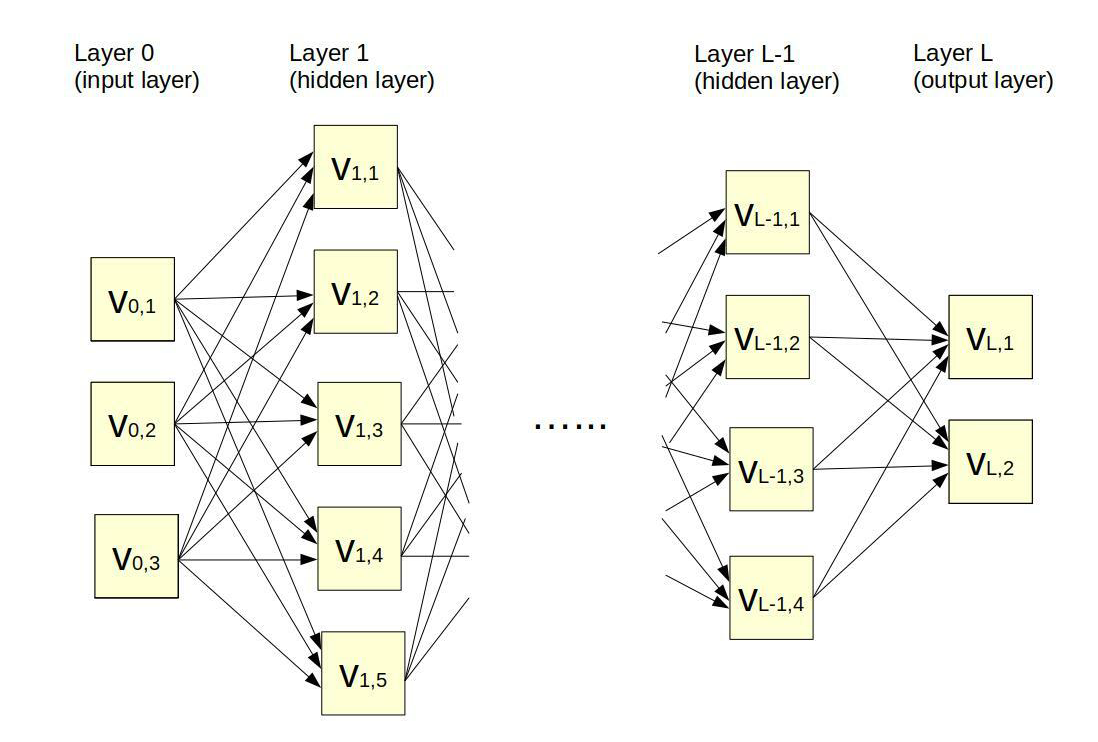

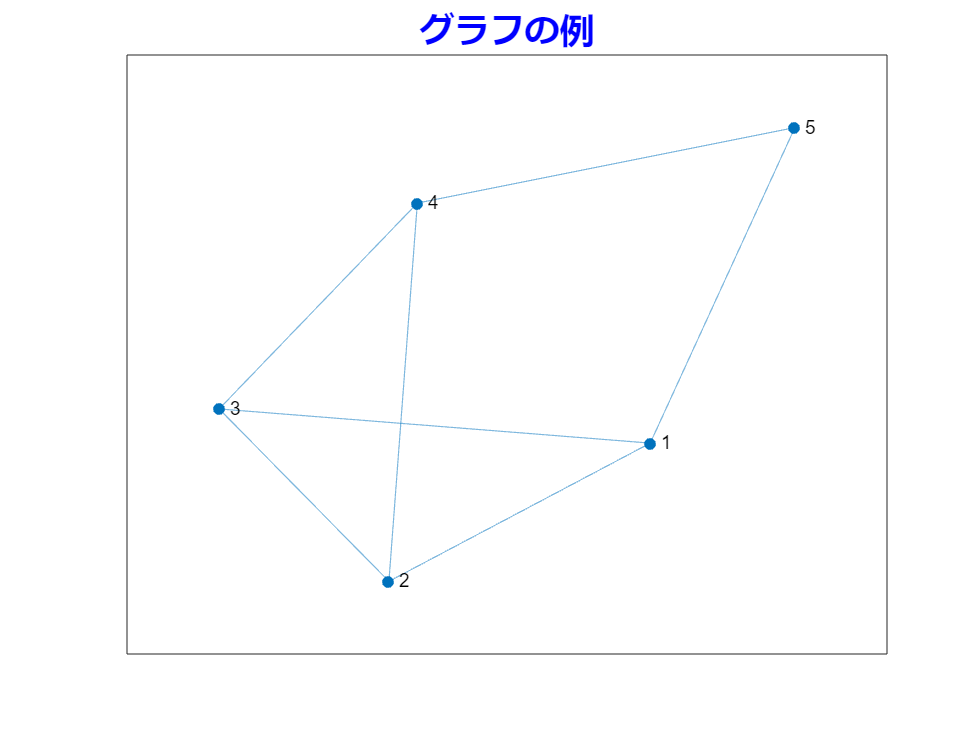

close;
A = [0 1 1 0 1; 1 0 1 1 0; 1 1 0 1 0; 0 1 1 0 1 ;1 0 0 1 0];
G=graph(A);
plot(G)
title('グラフの例','Color','blue','FontSize',15)

- **現状では大半のAIが幾何学的深層学習の例と見ることができる**：従来の深層学習・SNSのおすすめ・渋滞予測・**ChatGPTのような生成型AI**・創薬と改良・蛋白質の合成・物体の認識(機械視覚)・ゲーム(囲碁・将棋・チェス・オセロなど)・医療診断・素粒子実験・宇宙観測・VRなど...

### 1-2. computational thinking とは

担当教員は2022年6月に下記の講義 (60分×30回) を YouTube で聴講した以外の関りがないが...

- [**MIT 18.S191: Introduction to Computational Thinking**](https://computationalthinking.mit.edu/)

computational thinking とは、計算機を援用して数学 (Mathematics)､ 計算機科学 (Computer Science)､計算科学 (Computational Science) の理論や手法をあらゆる問題に適用して問題の可視化や問題解決を図ろう、という考え方であると担当教員は認識している。Computational Science は現在非常に活発な**学際的分野**で、Nature から専門誌が出版されているが、理工系を含む様々な既存の分野が Computational Science に吸収されていく。また Computational Science の中に Digital Medicine という創薬や画像医学などの Computational Science を積極的に援用する医学系の新しい学問分野が立ち上がって Nature や Lancet から専門誌が出版されている。

### 1-2-1. 1変数関数の微分可能性

1変数関数 $f(x)$ が $x=a$ で**微分可能**であるとは、ある実数 $\alpha$ とある関数 $R(x)$ が存在して


$$f(x) = \{f(a)+\alpha(x-a)\} + R(x),$$



$$\frac{R(x)}{x-a} \rightarrow 0 \quad (x \rightarrow a),$$


が $x=a$ の近くで成り立つことである。

この意味を理解するために、点 $\bigl(a,f(a)\bigr)$ を通る傾き $b$ の1次関数 


$$g(x;b) = f(a) + b(x-a)$$


を考えて $b$ を任意に動かしてみると


$$f(x) - g(x,\alpha) = R(x)$$



$$f(x) - g(x;b) = (\alpha - b)(x - a) + R(x)$$


となるので, $b = \alpha$ のときだけ $g(x;b)$ の ぐグラフは $f(x)$ のグラフに例外的に速く近づくことがわかる。

方程式 $y = g(x;\alpha)$ が表す直線は  $y = f(x)$ が表す曲線の点  $\bigl(a,f(a)\bigr)$ における接線とよばれる。

標語的には「関数がある点で微分可能であるとは、その点を通る接線がただ一つ存在すること」である。

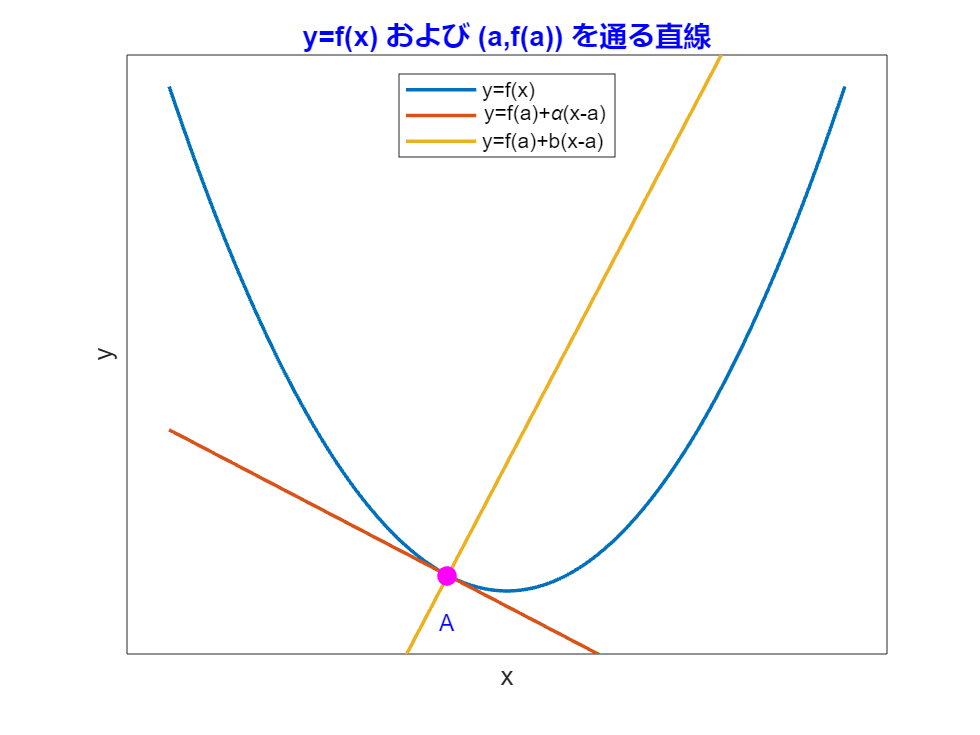

close;
a =-0.7; b =5.1;
p0=zeros(1,1);
q0=zeros(1,1);
p0(1,1)=a;
q0(1,1)=a^2;

x0 = -4:0.05:4;
f0=x0.^2;
g0=2*a*x0-a^2;
h0=b*x0-a*b+a^2;

f11=figure;
Y1=plot(x0,f0,x0,g0,x0,h0,'LineWidth',1.5);
   ylim([-2 17])
   xlim([-4.5 4.5])
   title('y=f(x) および (a,f(a)) を通る直線','Color','blue','FontSize',12)
   text(a-0.1,a^2-1.5,'A','Color','blue','FontSize',10) 
   xlabel('x')
   xticks([])
   ylabel('y')
   yticks([])
hold on
   sz0=70;
Y2=scatter(p0,q0,sz0,'filled','magenta');
hold off
legend([Y1],{'y=f(x)','y=f(a)+{\alpha}(x-a)','y=f(a)+b(x-a)'},'Location','north')

%set(gcf,'Position',[200,200,350,280]);

### 1-2-2. $\sin{x}$ のテイラー展開のコンパクト一様収束

すべての実数 $x$ に対して


$$\sin{x} =\sum_{n=0}^\infty \frac{(-1)^n}{(2n+1)!}x^{2n+1}$$


が成立することがよく知られている。右辺は $\sin{x}$ の $x=0$ におけるテイラー展開とよばれる。

右辺の級数は任意の有界閉区間 $[-R,R]$ 上で一様収束する：


$$\max_{-R \leq x \leq R}
\left|
\sin{x} - S_N(x)
\right| 
\rightarrow 0
\quad
(N \rightarrow \infty),$$



$$S_N(x) 
= 
\sum_{n=0}^N
\frac{(-1)^n}{(2n+1)!}x^{2n+1}.$$


これを観察してみよう。

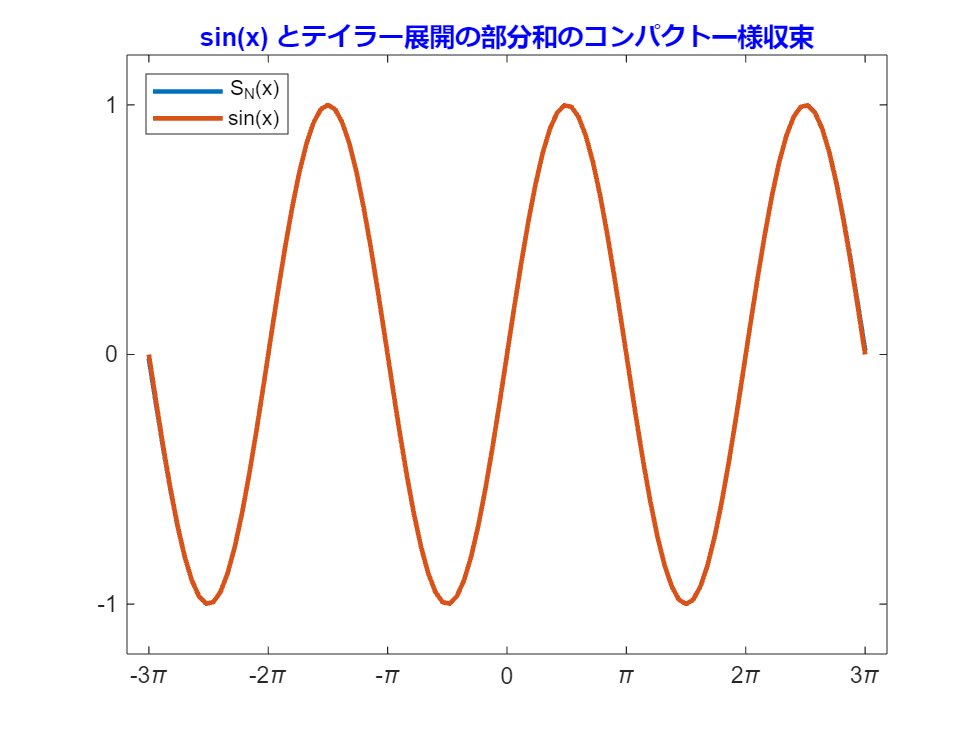

close;
L3 = 12;
x3 = linspace(-3*pi,3*pi,101);
y3 = zeros(L3+1,length(x3));
y3(1,:) = x3;
for k=2:L3+1
    y3(k,:)=y3(k-1,:)+power(-1,k-1)*power(x3,2*k-1)/factorial(2*k-1);    
end

N =12 ;
plot(x3,y3(N+1,:),x3,sin(x3),'LineWidth',2)
    ylim([-1.2 1.2])
    title('sin(x) とテイラー展開の部分和のコンパクト一様収束','Color','blue','FontSize',11)
    xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
    xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
    yticks([-1 0 1])
    yticklabels({'-1','0','1'})
    legend('S_N(x)','sin(x)','Location','northwest')

### 1-2-3. 2変数関数のグラフと微分可能性と接平面

2変数関数の(全)**微分可能性**とは雑に言うと関数のグラフ上の着目点を通る接平面が一意的に存在することである。

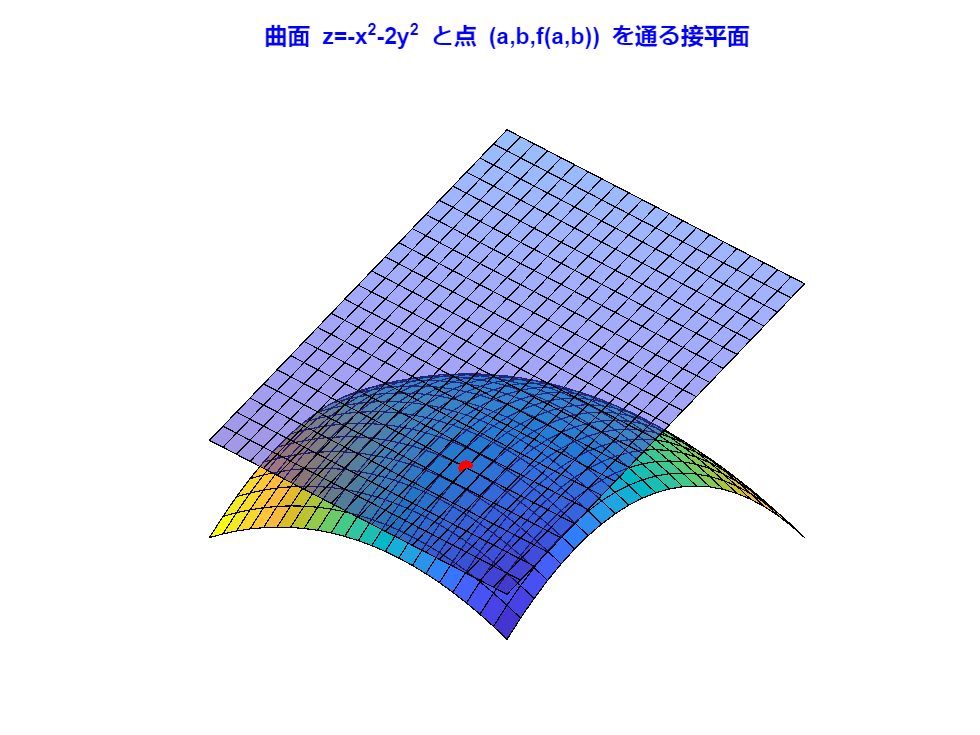

close;
l=-1.1:0.1:1.1; 
m=-1.1:0.1:1.1;
[u,v]=meshgrid(l,m);
x=u;
y=v;
z=-u.^2-2*v.^2;
C1=10*x.*y+10;

a =0.3; b =-0.6;

w=a^2+2*b^2-2*a*x-4*b*y;
X=[a];
Y=[b];
Z=[-a^2-2*b^2];

surf(x,y,z,C1);
axis off
xlim([-1.1 1.1])
ylim([-1.1 1.1])
view(45,20)
pbaspect([1 1 1])
title('曲面 z=-x^2-2y^2 と点 (a,b,f(a,b)) を通る接平面','Color','blue','FontSize',10)
hold on 
surf(x,y,w,'FaceAlpha',0.5);
scatter3(X,Y,Z,'filled','MarkerEdgeColor','red','MarkerFaceColor','red');
hold off

### 1-2-4. SIR モデルのシミュレーション

$t$を時刻、$\beta$と$\gamma$を正定数とする。3つの実数値未知関数 $S(t), I(t), R(t)$ に対する常微分方程式系


$$\frac{dS}{dt}=-\beta{IS},
\quad
\frac{dI}{dt}=\beta{IS}-\gamma{I},
\quad
\frac{dR}{dt}=\gamma{I}$$


はSIRモデルとよばれる感染症の集団的動向を記述するモデルとしてよく知られている。未知関数はそれぞれ時刻$t$における

- $S(t)$ : 感染することが可能な (susceptible) 人の数

- $I(t)$ : 感染している (infected) 人の数

- $R(t)$ : 回復した (recovered) 人の数

を表す。このモデルでは生まれる人や亡くなる人はいないことになっている。


$$\frac{d}{dt}(S+I+R)=0$$


よって短期間のシミュレーションにのみある程度有効である。2つの定数は単位時間当たりの

- $\beta$ : 感染者一人が感染させる人数

- $\gamma$ : 感染者一人が回復する割合

を表すが、これらは感染症の状況によって定まるもので感染症の状況を端的に表す。

以下は全人口を $S+I+R=1$ に正規化したシミュレーションの結果である。

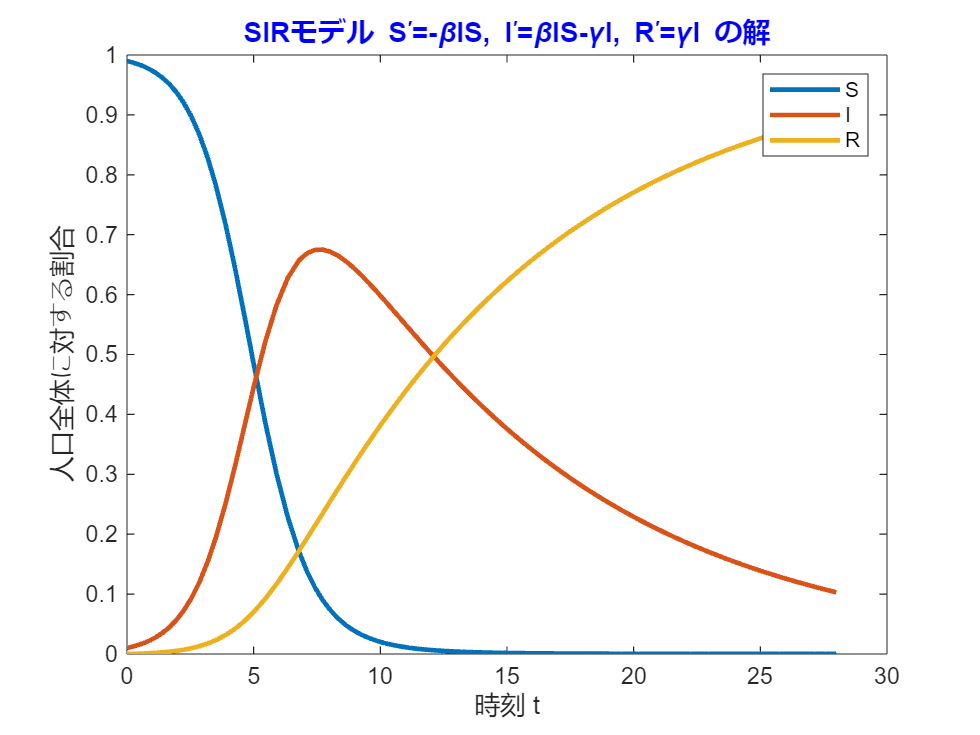

close;
beta =1.02 ;   gamma =0.1;
[t1,u1]=ode45(@(t,u) [-beta*u(1)*u(2); beta*u(1)*u(2)-gamma*u(2); gamma*u(2)], [0,28], [0.99;0.01;0]);

plot(t1,u1(:,1),t1,u1(:,2),t1,u1(:,3),'LineWidth',2); 
title('SIRモデル S^\prime=-\beta{IS}, I^\prime=\beta{IS}-\gamma{I}, R^\prime=\gamma{I} の解','Color','blue','FontSize',12); xlabel('時刻 t'); 
ylabel('人口全体に対する割合');
legend('S','I','R');

### 1-3. 公開データの活用と可視化

地球表面の平均気温の年間平均値の1961-1990の平均値からの差

[Our World in Data,  Average temperature anomaly, Global ](https://ourworldindata.org/grapher/temperature-anomaly)

このデータの CSV ファイル (地球全体と北半球と南半球)

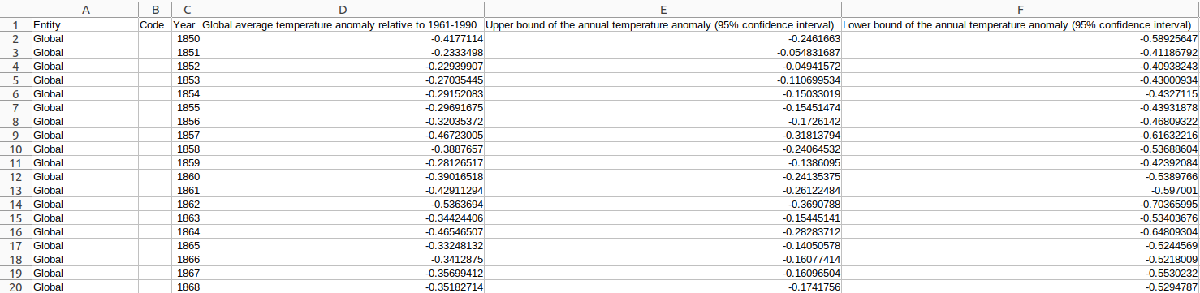

地球全体と北半球と南半球のデータを一緒に折れ線グラフにして可視化する。

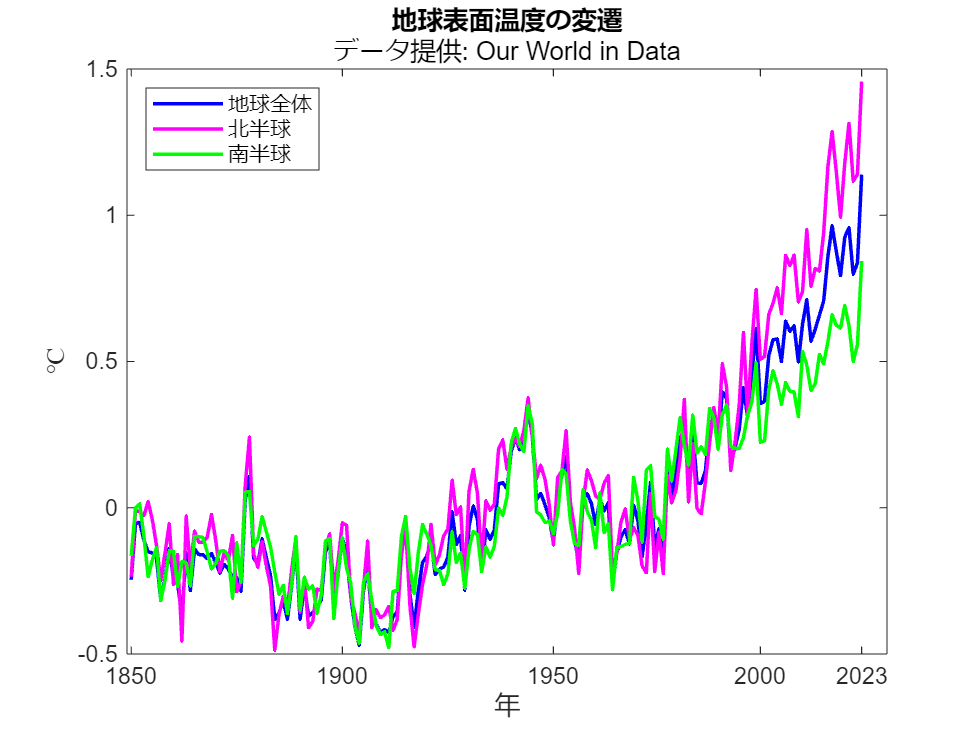

close;
X=importdata('./csv/temperature.csv');
Y=X.data(1:174,2);
W=X.data(1:174,4);
N=X.data(176:349,4);
S=X.data(351:524,4);

newcolors = [0 0 1; 
             1 0 1; 
             0 1 0];
colororder(newcolors) 
plot([W N S],'LineWidth',1.5)
title('地球表面温度の変遷','データ提供: Our World in Data')
xlabel('年')
ylabel('℃')
xticks([1 51 101 150 174])
xticklabels({1850,1900,1950,2000,2023})
legend('地球全体','北半球','南半球','Location','northwest');

[World Bank Group の1961-2023のGDP成長率のデータ](https://bit.ly/3WqUSIU)

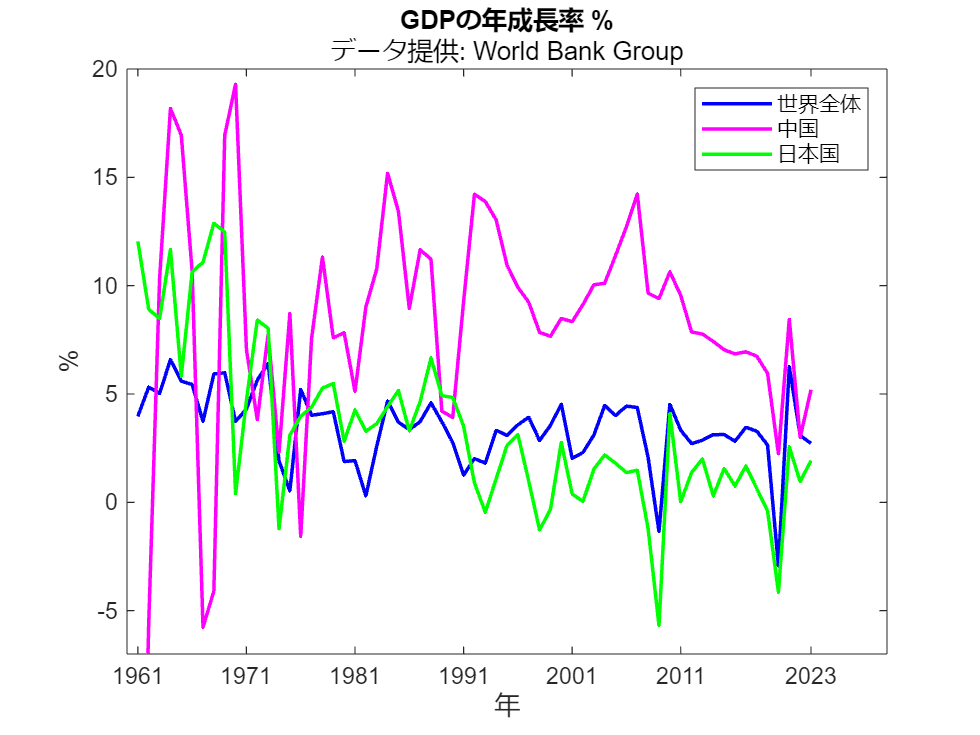

close;
GDP=importdata('./csv/gdp.csv');
WLD=GDP.data(261,1:63);
CHN=GDP.data(42,1:63);
JPN=GDP.data(121,1:63);

newcolors = [0 0 1; 
             1 0 1; 
             0 1 0];
colororder(newcolors) 
plot([WLD' CHN' JPN'],'LineWidth',1.5)
title('GDPの年成長率 %','データ提供: World Bank Group')
ylim([-7,20])
xlabel('年')
ylabel('%')
xticks([1 11 21 31 41 51 63])
xticklabels({1961,1971,1981,1991,2001,2011,2023})
legend('世界全体','中国','日本国','Location','northeast');

## 2. 数ベクトルや行列を扱う線形代数という数学


$$\pmatrix{1 \cr 2 \cr 3},
\quad
\pmatrix{1 & 2 & 3 & 4},
\quad
\pmatrix{1 & 2 & 3 \cr 4 & 5 & 6}$$


のように数を長方形状に並べて $(\ )$ または $[\ ]$ でくくったものは行列とよばれる. 

$\mathbb{R}$を実数の全体､$m,n=1,2,3,\ldots$, とする。より正確には


$$A
:=
\pmatrix{a_{11} & a_{12} & \cdots & a_{1n}
              \cr
              a_{21} & a_{22} & \cdots & a_{2n}
              \cr
              \vdots & \vdots & \ddots & \vdots
              \cr
              a_{m1} & a_{m2} & \cdots & a_{mn}},
\quad
a_{ij}\in\mathbb{R},
\quad
i=1,\ldots,m, 
\quad
j=1,\ldots,n$$


によって定義される $A$ は $m{\times}n$ 行列とよばれる. 特に $n=1$ の場合


$$\vec{a}
=
\pmatrix{a_1 \cr a_2 \cr \vdots \cr a_m}$$


を $m$ 次元列ベクトル、$m=1$の場合


$$\vec{b}
=
\pmatrix{b_1 & b_2 & \cdots & b_n}$$


を $n$ 次元行ベクトル、列ベクトルや行ベクトルを数ベクトルという。

$m{\times}n$ 行列 $A$ が与えられているとする。$n$ 次元列ベクトル $\vec{x}$ に左から$A$ をかけると $m$ 次元数ベクトル $A\vec{x}$ が生成され写像が定義される。例えば 


$$\pmatrix{x \cr y \cr z}
\mapsto 
\pmatrix{1 & 2 & 3 \cr 4 & 5 & 6}
\pmatrix{x \cr y \cr z}
:=
x
\pmatrix{1 \cr 4}
+
y
\pmatrix{2 \cr 5}
+
z
\pmatrix{3 \cr 6}
=
\pmatrix{x+2y+3z \cr 4x+5y+6z}$$


のようになる. これは数ベクトルの加法とスカラー倍を保存する写像である:


$$A(\alpha\vec{x}+\beta\vec{y})
=
\alpha(A\vec{x})+\beta(A\vec{y}).$$


この性質をもつ数ベクトルを数ベクトルにうつす写像を線形写像という。

**線形代数**

- 数ベクトル・行列・線形写像の基本的な事実を学ぶ。

- [文部科学省：高等学校 行列入門](https://www.mext.go.jp/a_menu/shotou/new-cs/senseiouen/1394142_00001.html)

- [放送大学 入門線型代数('19)](https://bangumi.ouj.ac.jp/v4/bslife/detail/17601141.html)

- [MIT 18.06: 世界で最も人気のある Gilbert Strang 教授の講義](https://ocw.mit.edu/courses/18-06-linear-algebra-spring-2010/)

- [2023年5月15日 Strang 教授の MIT 18.06 最終講義](https://www.youtube.com/watch?v=lUUte2o2Sn8)

## 3. 数ベクトルや行列の表すデータ

### 3-1. 1850年から2023年までの地球表面の年間平均気温の変遷(数ベクトル)

再び下記のデータを利用する。

[Our World in Data,  Average temperature anomaly, Global ](https://ourworldindata.org/grapher/temperature-anomaly)

temperature=W;
year=Y;
table(year,temperature)

ans = 174×2 table
    year    temperature
    ____    ___________

    1850      -0.24617 
    1851     -0.054832 
    1852     -0.049416 
    1853       -0.1107 
    1854      -0.15033 
    1855      -0.15451 
    1856      -0.17261 
    1857      -0.31814 
    1858      -0.24065 
    1859      -0.13861 
    1860      -0.24135 
    1861      -0.26122 
    1862      -0.36908 
    1863      -0.15445 
    1864      -0.28284 
    1865      -0.14051 


### 3-2. 音声信号 (数ベクトル)

音声データは連続的に聞こえるが、人間の耳にはそう聞こえるだけであり、実際には離散時間ごとのデータであり数ベクトルである。3秒程度の音声データを取り込んで図示する。1秒を$22050$に分割して(通常の高音質の半分)、$69520$ 次元の数ベクトルになっている。

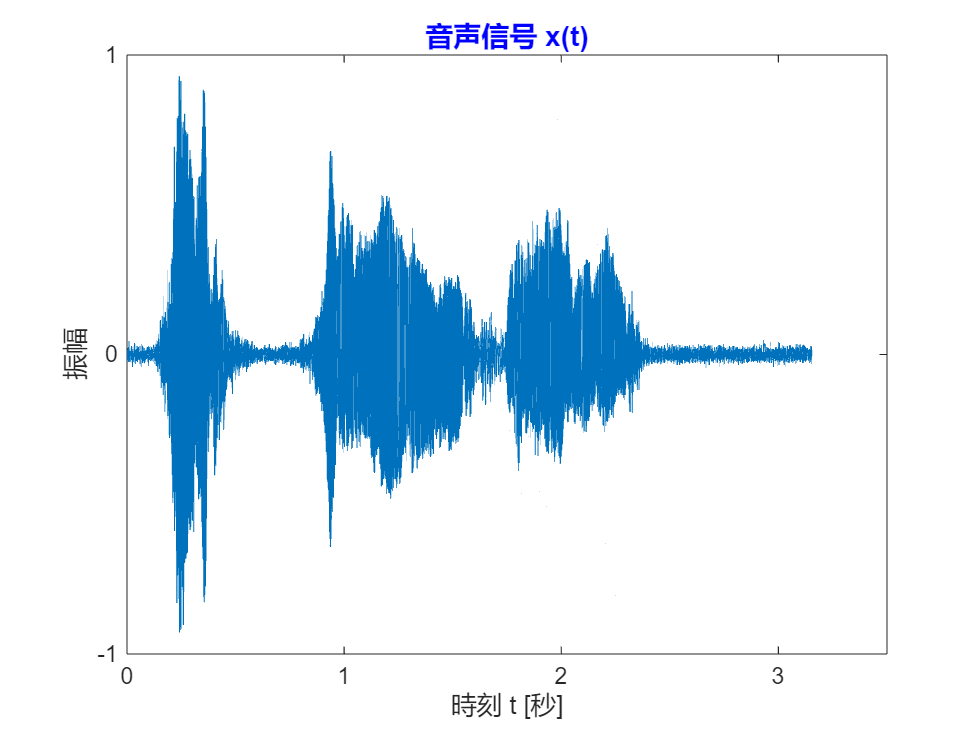

close;
f32=figure;
[W,fs] = audioread('./sound/cheese.wav');
fs=22050;
Ts=1/fs;
N=69520;
t=(0:N-1)*Ts;
plot(t,W);
title('音声信号 x(t)','Color','blue','FontSize',12);
xlabel('時刻 t [秒]');
xticks([0 1 2 3]);
ylabel('振幅');
yticks([-1 0 1])

%set(gcf,'Position',[200,200,400,300]);

### 3-3. データ行列 

$n$ 個の個体が $p$ 個の項目についてそれぞれ数値データを持っているとき、$n \times p$ 行列によって全データが表される。このような行列はデータ行列とよばれる。MATLAB が提供する架空のサンプルを利用して $100\times3$ の具体例を見てみよう。

load patients
SelfAssessedHealthStatus = categorical(SelfAssessedHealthStatus);
Height=floor(25.4*Height)/10;
Weight=floor(4.53592*Weight)/10;
T = table(Age,Height,Weight,'RowNames',LastName)

T = 100×3 table
                Age    Height    Weight
                ___    ______    ______

    Smith       38     180.3      79.8 
    Johnson     43     175.2      73.9 
    Williams    38     162.5      59.4 
    Jones       40     170.1      60.3 
    Brown       49     162.5      53.9 
    Davis       46     172.7      64.4 
    Miller      33     162.5      64.4 
    Wilson      40     172.7      81.6 
    Moore       28     172.7        83 
    Taylor      31     167.6      59.8 
    Anderson    45     172.7        58 
    Thomas      42     167.6      62.1 
    Jackson     25     180.3      78.9 
    White       39     182.8      91.6 
   

### 3-4. 白黒画像 (行列)

白黒画像 (grayscale image) は $0$ から $255$ までの整数を成分にもつ行列であり, $0$ は黒で数が増えると次第に白く明るくなって $255$ で白になる。例えば次の行列は


$$\pmatrix{0 & 15 & 30 & 45 & 60 & 75
              \cr
              90 & 105 & 120 & 135 & 150 & 165
              \cr
              180 & 195 & 210 & 225 & 240 & 255}$$


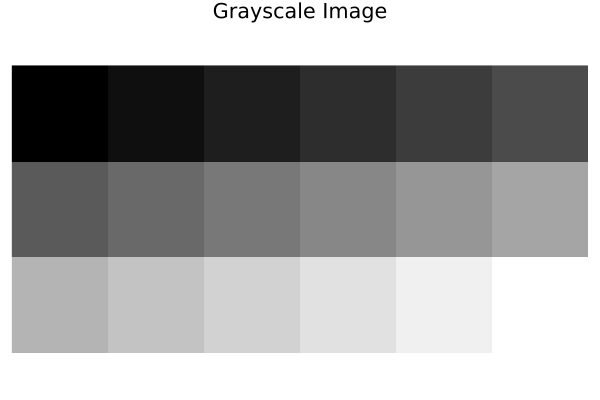

### 3-5. RGB画像 (同じサイズの行列の3つ組)

RGB画像は同じサイズの白黒画像の3つを三原色 R (red), G (green), B (blue) で色付けして重ね合わせたものである。乱数生成機能で $10\times15$ 行列を3つ生成し, それぞれ赤、緑、青で色付けして重ねてみる。

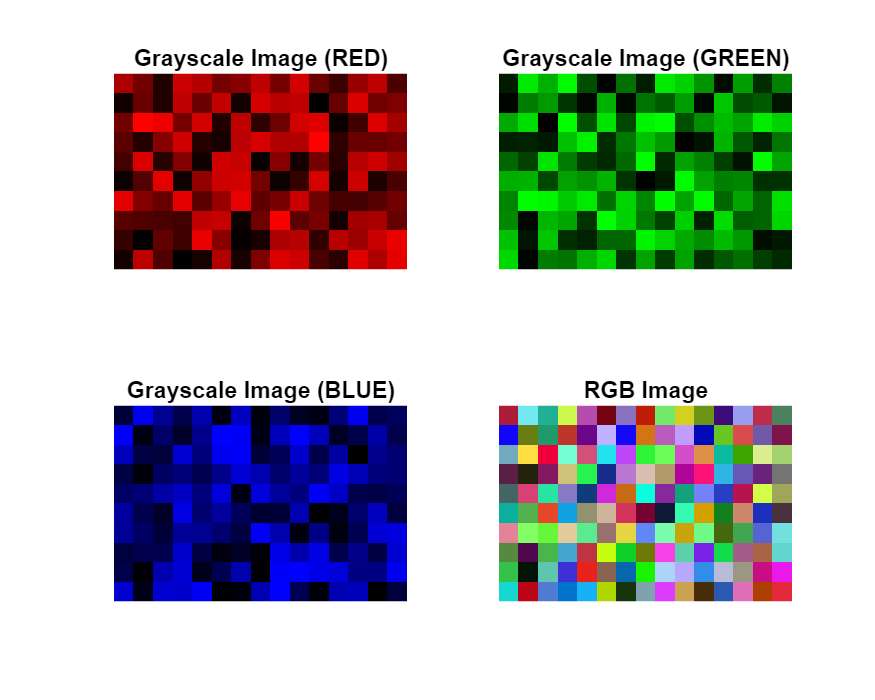

close;
A35=mat2gray(rand(10,15));
B35=mat2gray(rand(10,15));
C35=mat2gray(rand(10,15));
blank35=mat2gray(zeros(10,15));
X35(:,:,1)=A35;
X35(:,:,2)=blank35;
X35(:,:,3)=blank35;
Y35(:,:,1)=blank35;
Y35(:,:,2)=B35;
Y35(:,:,3)=blank35;
Z35(:,:,1)=blank35;
Z35(:,:,2)=blank35;
Z35(:,:,3)=C35;
RGB35(:,:,1)=A35;
RGB35(:,:,2)=B35;
RGB35(:,:,3)=C35;

f35=figure;
subplot(2,2,1)
imshow(X35,'InitialMagnification',1000);
title('Grayscale Image (RED)');
subplot(2,2,2)
imshow(Y35,'InitialMagnification',1000);
title('Grayscale Image (GREEN)');
subplot(2,2,3)
imshow(Z35,'InitialMagnification',1000);
title('Grayscale Image (BLUE)');
subplot(2,2,4)
imshow(RGB35,'InitialMagnification',1000);
title('RGB Image');
set(gcf,'Position',[200,200,500,400]);

### 3-6. 白黒動画 (行列の列)

乱数生成機能で$10\times15$ 行列を生成することを60回繰り返す。生成されたデータは$10\times15$ 行列の60個の列と見ることができる。

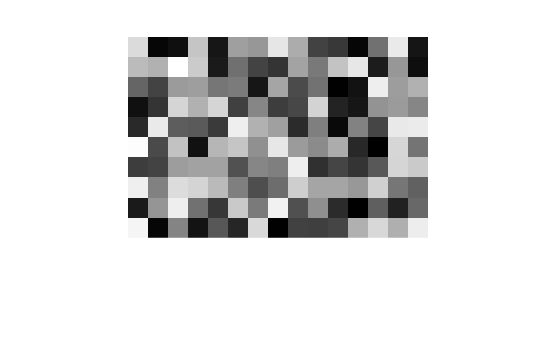

close;
for k=1:60
    Y36=mat2gray(rand(10,15));
    imshow(Y36,'InitialMagnification',2000);
    drawnow nocallbacks
    pause(0.5)
end

## 4. データ処理と線形代数

データ処理は線形代数における初等的な演算であるものが非常に多い。

### 4-1. 1次元データの平均と偏差ベクトル

$n$ 個のデータが $n$ 次元列ベクトル


$$\vec{x}
=
\pmatrix{x_1 \cr x_2 \cr \vdots \cr x_n}, 
\quad
x_1,x_2,\ldots,x_n \in \mathbb{R}$$


で与えられたとする。このとき $\vec{x}$ の平均 $a$ は


$$a
:=
\frac{1}{n}
\sum_{i=1}^nx_i$$


によって与えられる. 各成分から平均値を差し引いた


$$\vec{y}
=
\pmatrix{x_1-a \cr x_2-a \cr \vdots \cr x_n-a}$$


は $\vec{x}$ の偏差ベクトルとよばれ, $\vec{x}$ のばらつきを表しているのは直観的には明らかであろう。偏差ベクトルから分散や標準偏差などのデータの特徴を表す様々な情報が定義される。実はこれらの情報は線形代数に現れる基本的な演算にすぎないことを見てみよう。実際、平均は偏差ベクトルは数ベクトルの行列としての積


$$a
=
\frac{1}{n}
\pmatrix{1 & 1 & \ldots & 1}
\vec{x}, 
\quad
\vec{y}
=
\vec{x} 
-
a
\pmatrix{1 \cr 1 \cr \vdots \cr 1}
=
\vec{x}
-
\frac{1 }{n}
\pmatrix{1 & 1 & \ldots & 1}
\vec{x}
\pmatrix{1 \cr 1 \cr \vdots \cr 1}$$


によって与えられる。ここに


$$\pmatrix{1 & 1 & \ldots & 1},
\qquad
\pmatrix{1 \cr 1 \cr \vdots \cr 1}$$


はそれぞれすべての成分が $1$ である $n$ 次元行ベクトルと $n$ 次元列ベクトルである。MATLAB に限らずプログラミング言語ではすべての成分が $1$ であるような行列や数ベクトルは一言 

 でそれぞれ定義されて非常に使いやすくなっている。一方、最大値や最小値を求めるのは線形代数の演算ではない。[2024年7月1日から7月10日の那覇市の最高気温](https://bit.ly/3y5ps10)の平均、最大値、最小値、偏差ベクトルなどを見てみよう

close;
X=[33.2 33.9 34.5 34.4 35.0 34.7 34.3 35.0 33.6 33.6]'

X =    33.2000
   33.9000
   34.5000
   34.4000
   35.0000
   34.7000
   34.3000
   35.0000
   33.6000
   33.6000


ave=sum(X)/length(X); M=max(X); m=min(X);
item=['最大値';'平均値';'最小値'];
value=[M;ave;m];
table(item,value)

ans = 3×2 table
    item     value
    _____    _____

    最大値       35
    平均値    34.22
    最小値     33.2


Y=X-ones(1,10)*X*ones(10,1)/10

Y =    -1.0200
   -0.3200
    0.2800
    0.1800
    0.7800
    0.4800
    0.0800
    0.7800
   -0.6200
   -0.6200


### 4-2. 線形回帰分析の例

3-3の100人の架空のデータについて $x= $ 身長, $y=$ 体重のデータの組 $(x,y)$ を散布図で表す。

最小二乗法によってこの分布に最も1次式


$$y=\beta_0+\beta_1x$$


を求める。$\beta_0, \beta_1$ は線形代数の初等的操作だけで求めることができる。

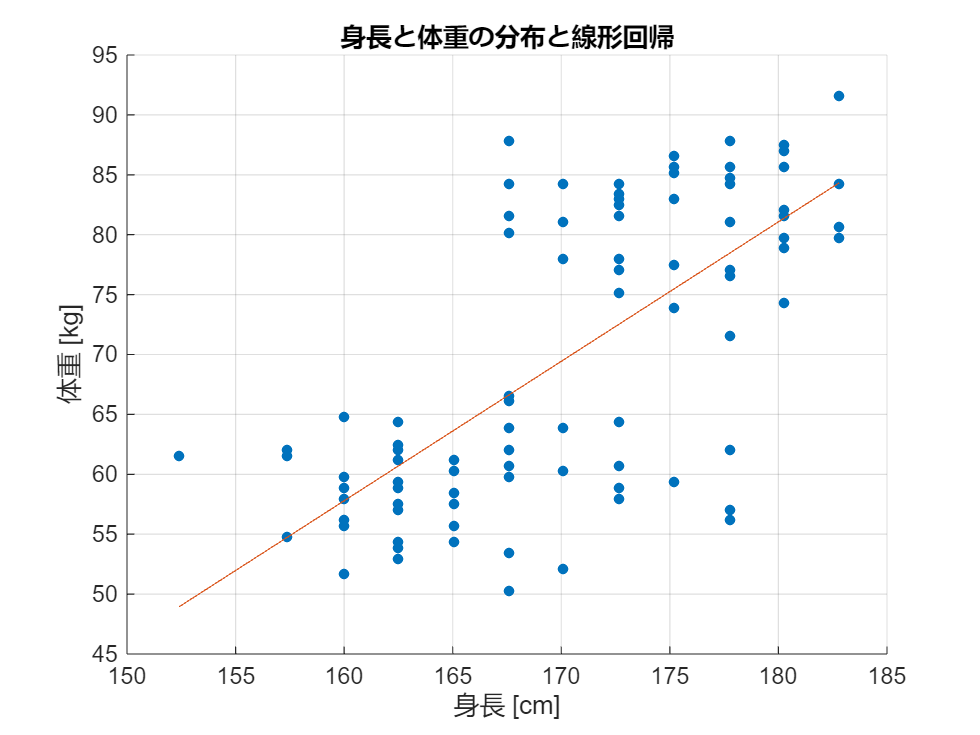

X = [ones(length(Height),1) Height];
b = X\Weight;
yCalc1 = X*b;
scatter(Height,Weight,20,'filled')
hold on
plot(Height,yCalc1)
xlabel('身長 [cm]')
ylabel('体重 [kg]')
title('身長と体重の分布と線形回帰')
grid on

### 4-3. 信号処理の例 (スペクトログラム)

3-2. 音声信号 (数ベクトル) の例を時刻と周波数に細分解して、絶対値を色で表し時刻と周波数の平面上にプロットしてみよう。 これはスペクトログラムとよばれ、音楽など音声信号に関わる様々な分野で利用されている。離散時間信号からスペクトログラムを得る過程は「絶対値をとる操作」以外はすべて行列と数ベクトルに行列の積をとる操作であり非常に簡単である。同じことを連続変数の関数に対して行う操作は関数の超局所化とよばれるが、**超局所解析**というかなり高度な数学理論が基盤である。

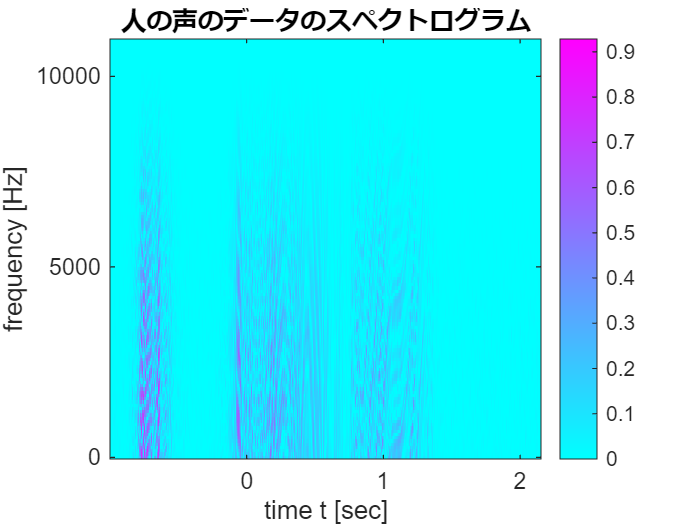

close;
f32=figure;
[W,fs] = audioread('./sound/cheese.wav');
fs=22050;
Ts=1/fs;
N=69520;
t=(0:N-1)*Ts;
L=256;
M=256;
N0=250;
n0=1+floor((N-L)/(L-N0));
s=L-N0;
l=transpose(1:L);
k=transpose(1:M/2+1);
m=1:M;
j=1:n0;

% window
w=hann(L);

% sampling and locarization
Y=zeros(L,n0);
Y(l,j)=w(l,1).*W(s.*(j-1)+l);

% sqrt(M) times Fourier matrix
omega=exp(2*pi*i/M);
F=zeros(M);
F(l,m)=power(omega,-(l-1).*(m-1));

% discrete short-time Fourier transform
Z=F*Y;

% spectrogram
X=zeros(M/2+1,n0);
X(k,j)=abs(Y(k,j));

% plotting
imagesc(X);
colorbar;
colormap(cool)
xticks([0 fs.*n0/N 2*fs.*n0/N 3*fs.*n0/N])
xticklabels({'0','1','2','3'})
xlabel('time t [sec]')
yticks([129*2050/22050 129*12050/22050 129])
yticklabels({'10000','5000','0'})
ylabel('frequency [Hz]')
title('人の声のデータのスペクトログラム')
set(gcf,'Position',[200,200,400,300]);

### 4-4. 画像処理の例 1 (低階最良近似)

線形代数でよく知られた特異値分解とよばれる行列の素顔を露わにする行列の標準形の理論を利用して行列をより小さいデータで近似することができる。RGB画像の処理の例を見てみよう。R,G,B のいずれもランク$300$の$300\times400$の行列を非常に低いランクの行列で近似する。

close;
% l. oad image file
RGB=imread('./image/CityU.jpg');
[s1,s2,s3]=size(RGB);
R2=max(s1,s2);
RGB=imresize(RGB, 1/8);
[R,G,B] = imsplit(RGB);
% imshow(RGB)
% whos R, whos G, whos B

DR=double(R);
DG=double(G);
DB=double(B);

for r=1:100
    [UR,SR,VR]=svds(DR,r);
    DRr=UR*SR*VR';
    Rr=uint8(DRr);
    [UG,SG,VG]=svds(DG,r);
    DGr=UG*SG*VG';
    Gr=uint8(DGr);
    [UB,SB,VB]=svds(DB,r);
    DBr=UB*SB*VB';
    Br=uint8(DBr);
    SVD(:,:,1,r)=(Rr);
    SVD(:,:,2,r)=(Gr);
    SVD(:,:,3,r)=(Br);
end

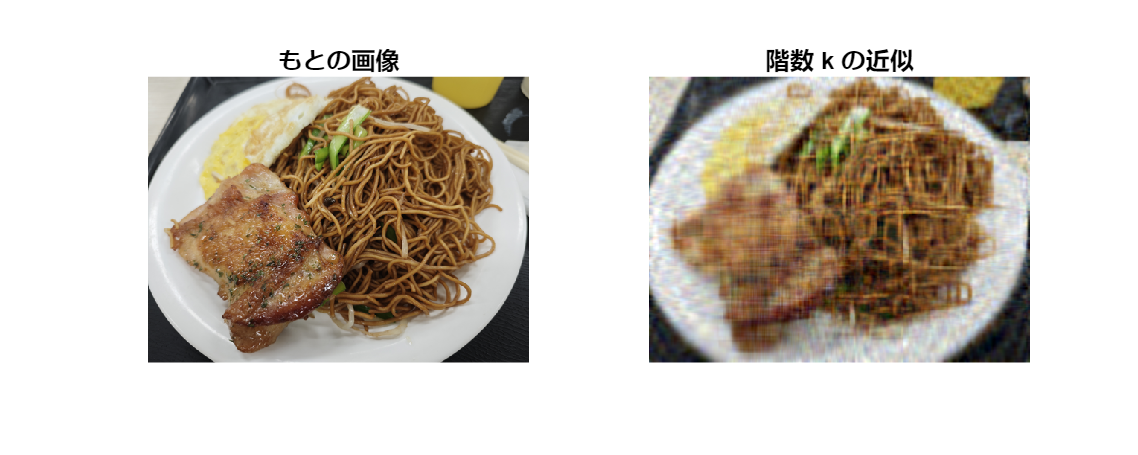

k =20;
subplot(1,2,1);
imshow(RGB);
title('もとの画像');
subplot(1,2,2);
imshow(SVD(:,:,:,k));
title('階数 k の近似');
set(gcf,'Position',[200,200,1200,480]);
saveas(gcf,'svd.png');

### 4-5. 画像処理の例 2 (ハール・ウェーブレットによるウェーブレット分解)

ウェーブレットとはある性質をみたす2つの数ベクトルの組でのことである。

最も単純なのは次のハール・ウェーブレットである。


$$\vec{u}
=
\frac{1}{\sqrt{2}}
\pmatrix{1 \cr 1 \cr 0 \cr \vdots \cr 0},
\quad
\vec{v}
=
\frac{1}{\sqrt{2}}
\pmatrix{1 \cr -1 \cr 0 \cr \vdots \cr 0}.$$


これを用いると数ベクトルや行列の隣接する成分の平均をとるという操作を線形代数だけを用いて系統的に定義することができる。2回の操作で


$$\vec{a}_0=\pmatrix{1 \cr 3 \cr 5 \cr 7}
\mapsto 
\vec{a}_1=\pmatrix{2 \cr 2 \cr 6 \cr 6}
\mapsto
\vec{a}_2=\pmatrix{4 \cr 4 \cr 4 \cr 4}$$



$$A_0
=
\pmatrix{0 & 2 & 4 & 6 
              \cr
              8 & 10 & 12 & 14
              \cr
              16 & 18 & 20 & 22
              \cr
              24 & 26 & 28 & 30}
\mapsto 
A_1
=
\pmatrix{5 & 5 & 9 & 9
              \cr
              5 & 5 & 9 & 9 
              \cr
              21 & 21 & 25 & 25 
              \cr
              21 & 21 & 25 & 25 }
\mapsto 
A_2
=
\pmatrix{15 & 15 & 15 & 15
              \cr
              15 & 15 & 15 & 15
              \cr
              15 & 15 & 15 & 15
              \cr
              15 & 15 & 15 & 15}$$


のようになる。平均をとる操作を $\ell$ 回行って得られる $\vec{a}_\ell$ や $A_\ell$ をレベル $\ell$ の近似部分、残りの $\vec{a}_0-\vec{a}_\ell$ や $A_0-A_\ell$ をレベル $\ell$ の詳細部分という。画像データのウェーブレット分解を観察してみよう。

MATLAB はこの操作が苦手なので Julia Programming Language で実施する。